Setup and function testing

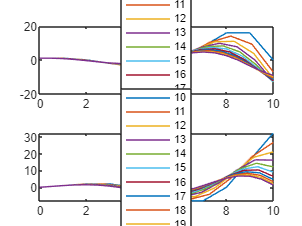

clc;
clear;
close all;

A = [0,-1;1,0];
x_0 = 1;
y_0 = 0;
T = 10;

Ns = 10:20;

% Euler's method

figure;

ax1 = subplot(2,1,1);
for N = Ns
    [t, x, y] = EMsolver(A, x_0, y_0, T, N);
    plot(ax1, t, x);
    hold on;
end

legend(string(Ns), Location="best");
title(ax1, "x(t)");

ax2 = subplot(2,1,2);
for N = Ns
    [t, x, y] = EMsolver(A, x_0, y_0, T, N);
    plot(ax2, t, y);
    hold on;
end

legend(string(Ns), Location="best");
title(ax2, "y(t)");

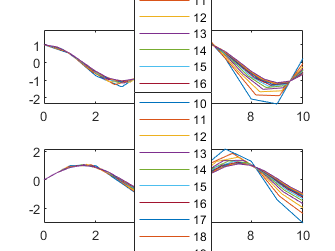


% Improved Euler's method

figure;

ax3 = subplot(2,1,1);
for N = Ns
    [t, x, y] = IEMsolver(A, x_0, y_0, T, N);
    plot(ax3, t, x);
    hold on;
end

legend(string(Ns), Location="best");
title(ax3, "x(t)");

ax4 = subplot(2,1,2);
for N = Ns
    [t, x, y] = IEMsolver(A, x_0, y_0, T, N);
    plot(ax4, t, y);
    hold on;
end

legend(string(Ns), Location="best");
title(ax4, "y(t)");

EMsolver and IEMsolver function

function [t, x, y] = EMsolver(A, x_0, y_0, T, N)
    dt = T/N;
    t = 0:dt:T;

    SOL = NaN(2,length(t));
    SOL(1,1) = x_0;
    SOL(2,1) = y_0;
    
    for k = 2:length(t)
        SOL(:,k) = SOL(:,k-1) + dt*A*SOL(:,k-1);
    end
    
    x = SOL(1,:);
    y = SOL(2,:);
end

function [t,x,y] = IEMsolver(A, x_0, y_0, T, N)
    dt = T/N;
    t = 0:dt:T;

    SOL = NaN(2, length(t));
    SOL(1,1) = x_0;
    SOL(2,1) = y_0;

    for k = 2:length(t)
        zn = SOL(:,k-1);
        SL = A * zn;
        SR = A * (zn + dt * SL);
        SOL(:,k) = zn + (dt / 2) * (SL + SR);
    end

    x = SOL(1,:);
    y = SOL(2,:);
end